## Assignment Section

### Exercise 1: Covariance and Correlation Matrices

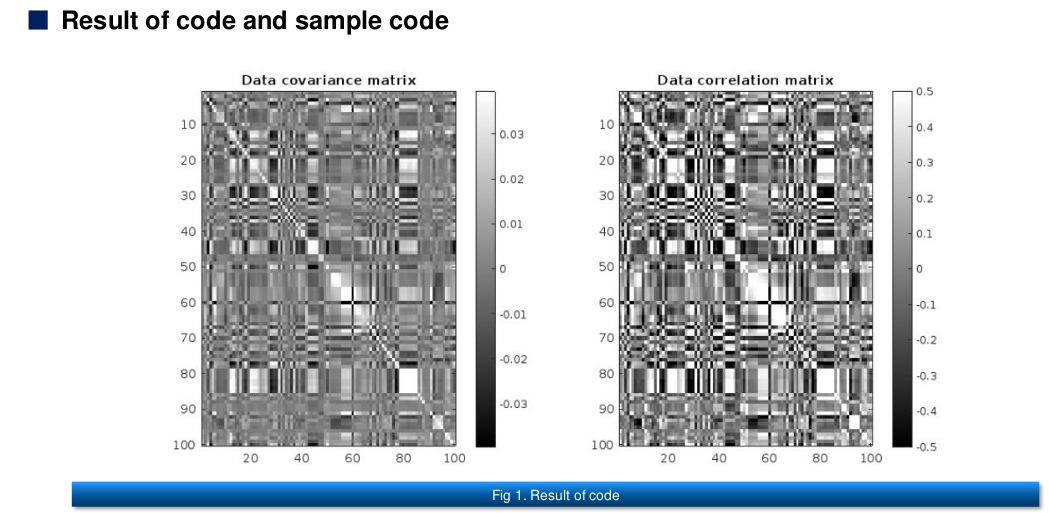

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the path to the CSV file
data_path = 'dataMat.csv';

% Read the data from the URL into a table
data = readtable(data_path, 'FileType', 'text', 'Delimiter', ',');
dataMat = table2array(data);

% write here (start)
% Compute the mean of each data feature
datamean = mean(dataMat,1);

% Mean-center the data
dataMatM = dataMat - repmat(datamean, size(dataMat, 1), 1);

% Confirm that any given feature has mean=0 (or very close...)
disp('Mean of the first feature after centering: ');

Mean of the first feature after centering: 


disp(mean(dataMatM(:, 1)))

  -9.9107e-17



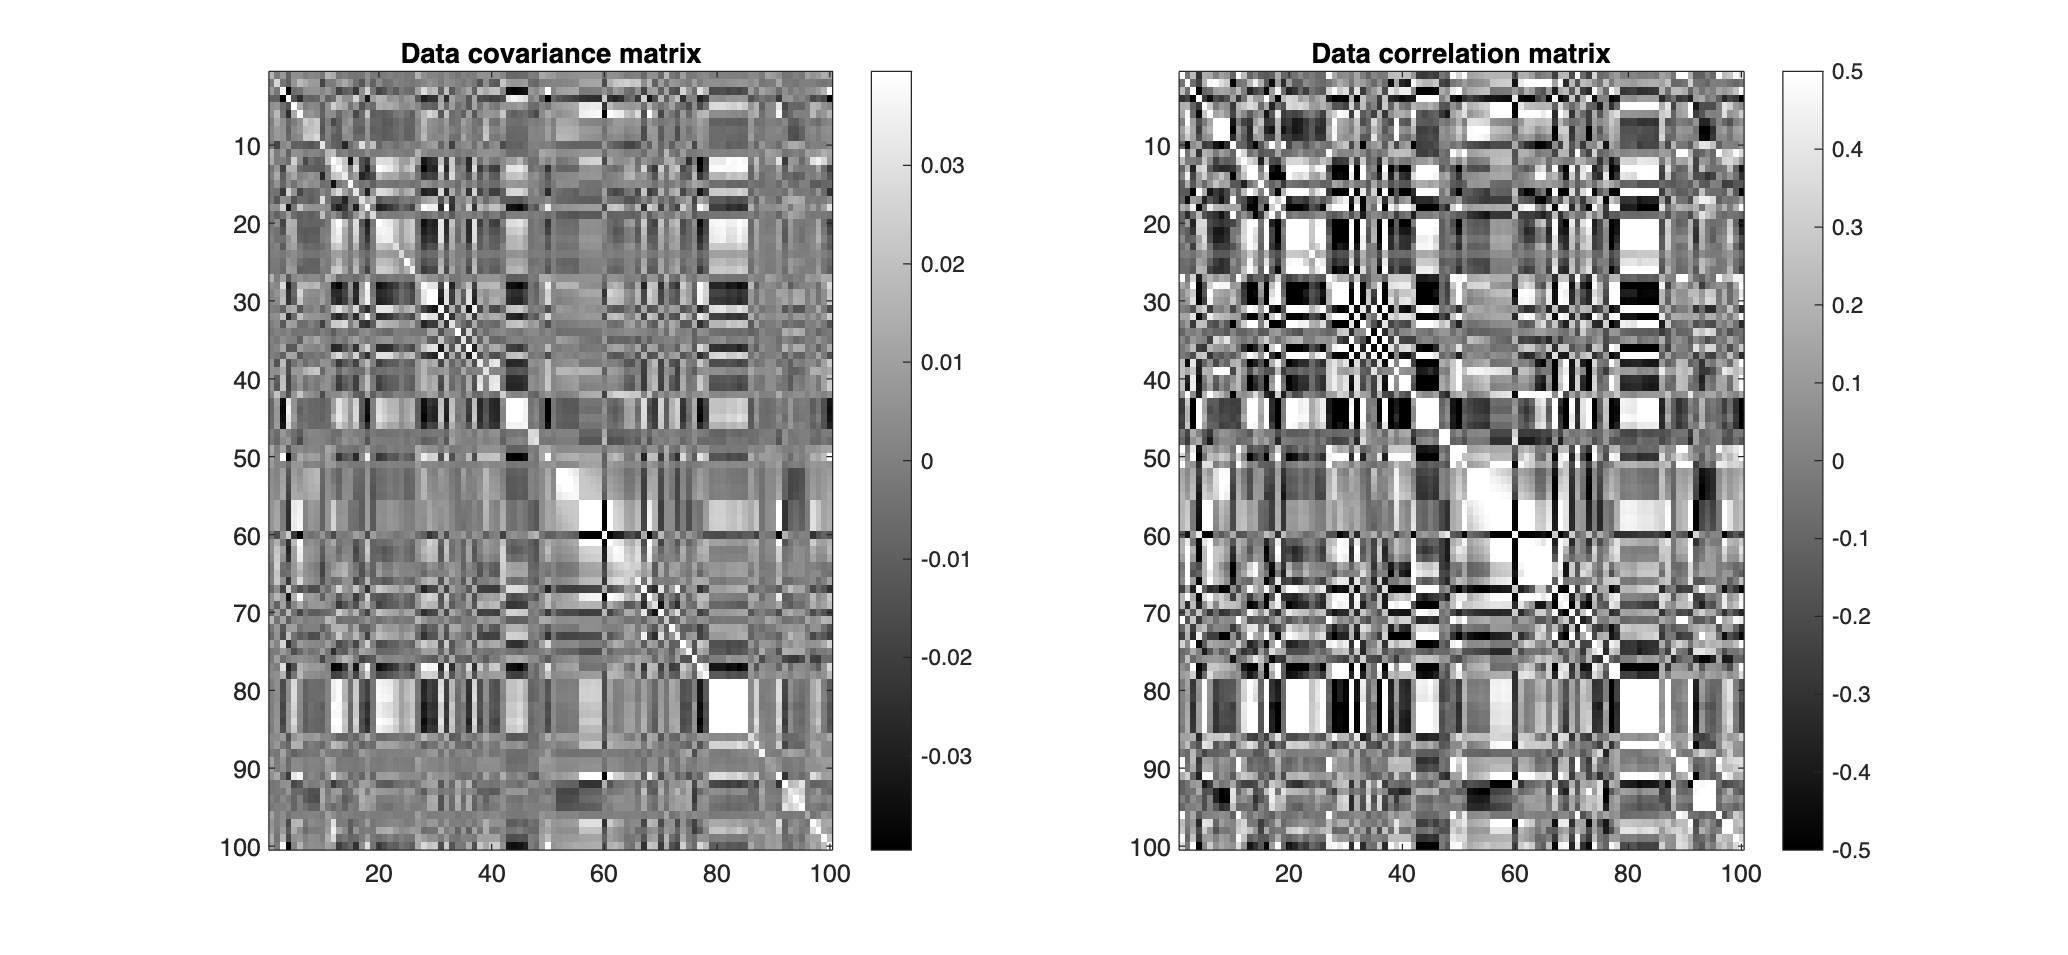


% Compute the covariance matrix
covMat =cov(dataMatM);

% Diagonal matrix of inverse standard deviations
variances = diag(covMat); % Extract diagonal elements (variances) from the covariance matrix
standard_devs = sqrt(variances);
S = diag(1 ./ standard_devs); % Create diagonal matrix of inverse standard deviations

% Compute the correlation matrix
% R = S*C*S
corrMat = S*covMat*S;

% write here (end)

% Dynamic color scaling
% Just for visualization
clim = max(abs(covMat(:))) * 0.2;

% Visualization of the covariance and correlation matrices
figure('Position', [100, 100, 1300, 600]);

% Plot the covariance matrix
subplot(1, 2, 1); % First subplot
imagesc(covMat, [-clim, clim]); % Display the covariance matrix
colormap('gray'); % Use gray colormap
title('Data covariance matrix', 'FontWeight', 'bold');
colorbar; % Show color scale

% Plot the correlation matrix
subplot(1, 2, 2); % Second subplot
imagesc(corrMat, [-0.5, 0.5]); % Display the correlation matrix
colormap('gray'); % Use gray colormap
title('Data correlation matrix', 'FontWeight', 'bold');
colorbar; % Show color scale

### Exercise 2: Geometric Transformations

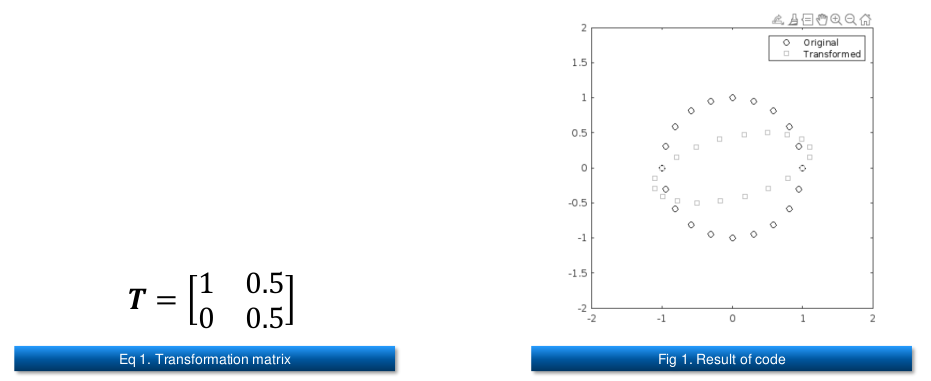

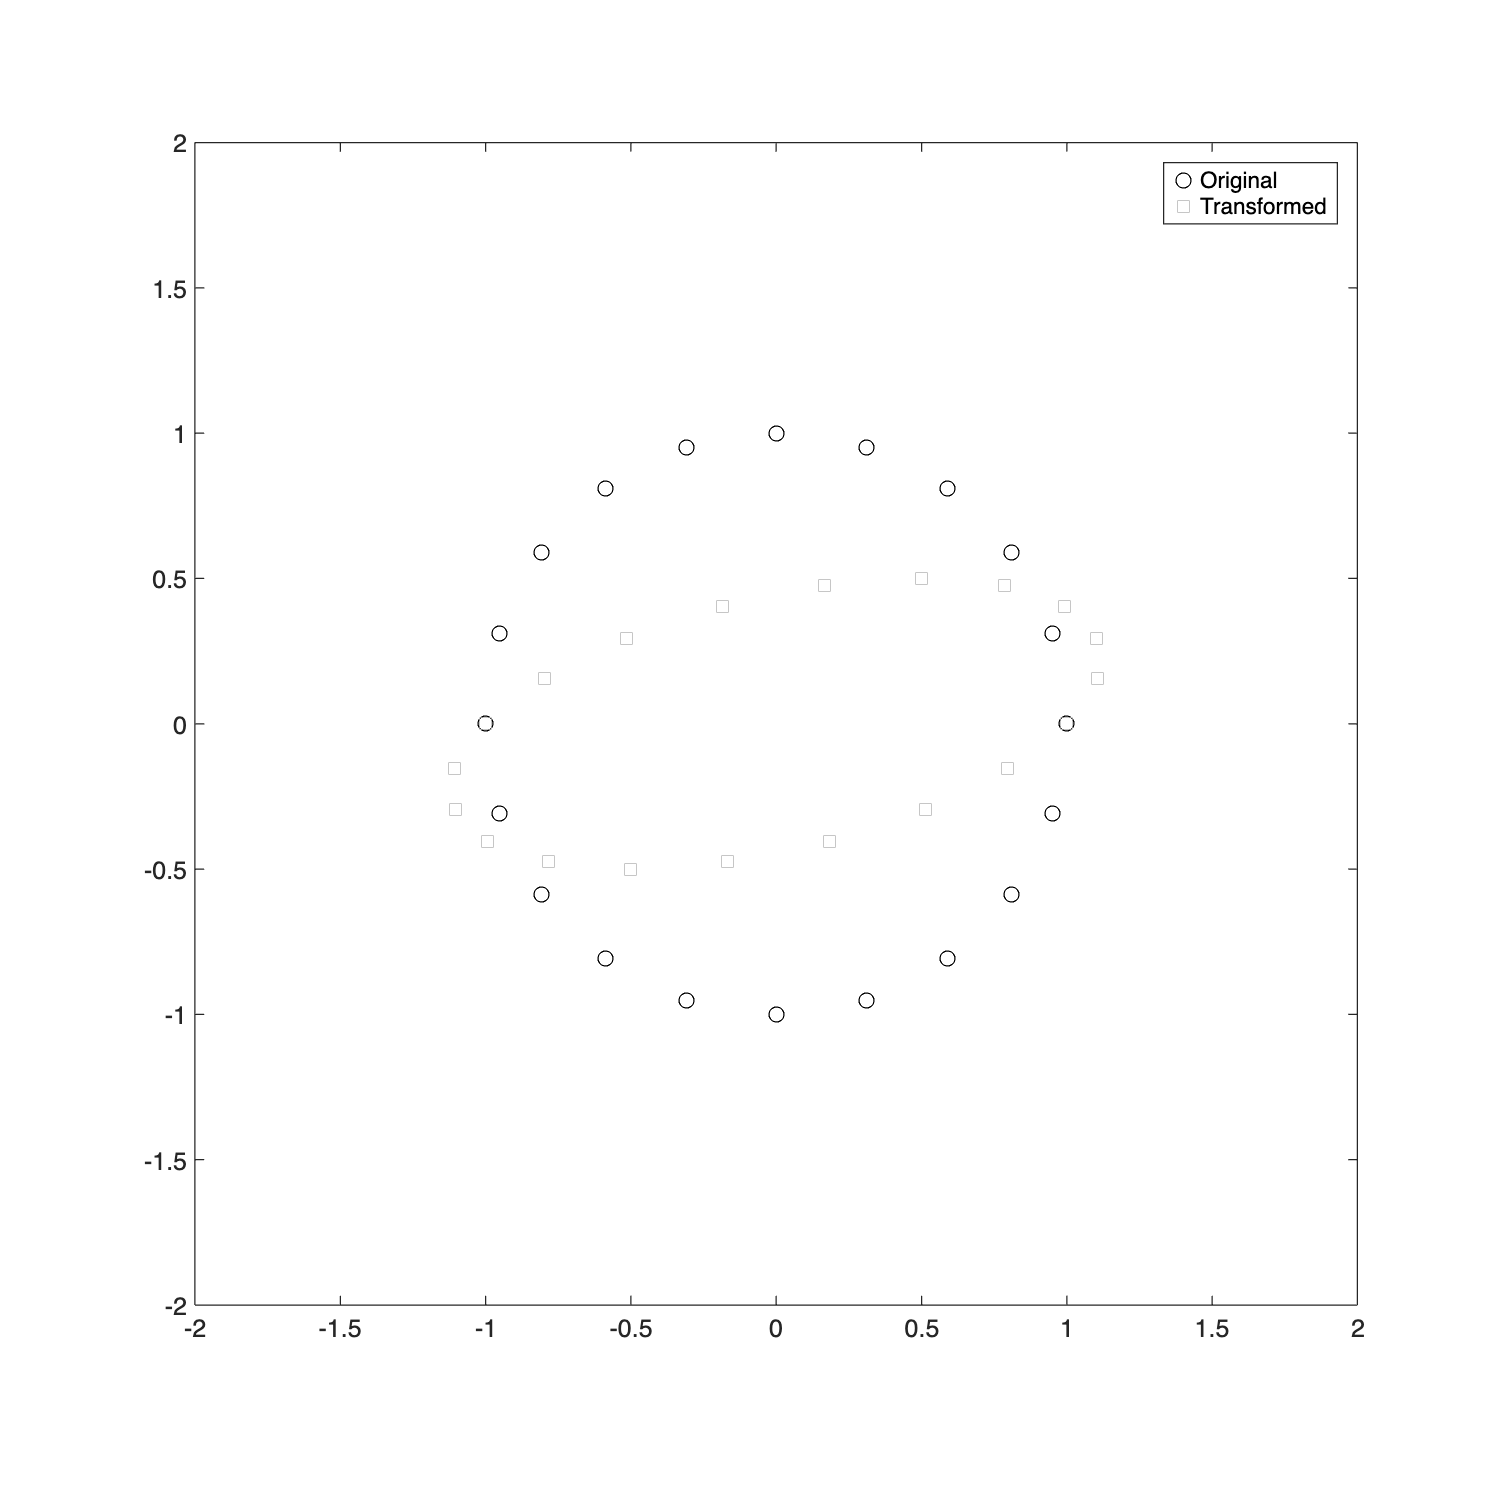

% ■ The goal of this exercise is to show points in a circle before and after applying a
% transformation
% ■ Use Eq 1. and then create a graph that looks like Fig 1..
% Clear workspace, command window, and close all figures
clc; clear; close all;

% Write here (start)
% Transformation matrix
T =[1 0.5; 
    0 0.5];
% Write here (end)

% Define the set of points (a circle)
theta = linspace(0, 2*pi - 2*pi/20, 20);
origPoints = [cos(theta); sin(theta)];

% Write here (start)
% Apply transformation
transformedPoints = T * origPoints;
% Write here (end)

% Plot the points
figure('Position', [100, 100, 600, 600]); % Create a figure window
plot(origPoints(1,:), origPoints(2,:), 'ko'); hold on; % Plot original points
plot(transformedPoints(1,:), transformedPoints(2,:), 's', 'Color', [0.7, 0.7, 0.7]); % Plot transformed points

axis square;
xlim([-2, 2]);
ylim([-2, 2]);
legend('Original', 'Transformed'); % Correctly add legend here

### Exercise 3: Image Feature Detection

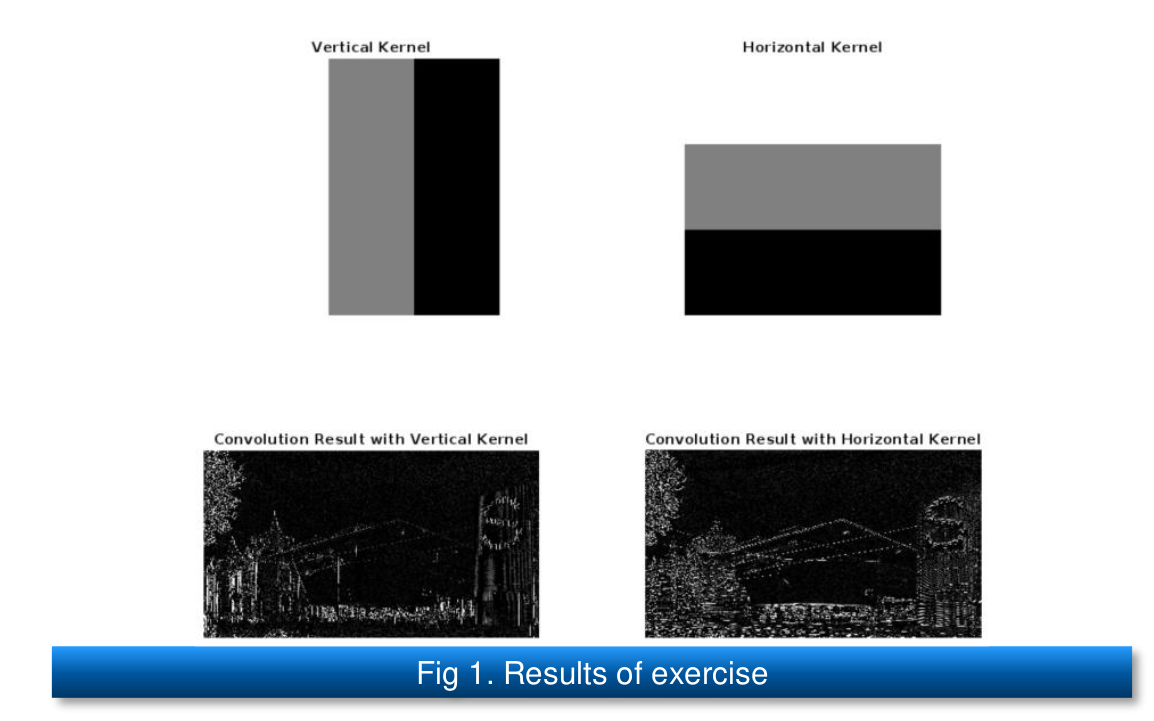

% ■ Technically, image smoothing is feature extraction, because it involves extracting
% the smooth features of the signal while dampening the sharp features. Here we will
% change the filter kernels to solve other image feature detection problems: identifying
% horizontal and vertical lines.
% ■ The two kernels are shown in Fig 1., as are their effects on the image. You can
% handcraft the two kernels based on their visual appearance; they are 𝟑 × 𝟑 and
% comprise only the numbers −𝟏, 𝟎 and +𝟏. Convolve those kernels with the 2D
% grayscale picture to create the feature maps shown in Fig 1..

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Read an image from the web
url = 'https://upload.wikimedia.org/wikipedia/commons/6/61/De_nieuwe_vleugel_van_het_Stedelijk_Museum_Amsterdam.jpg';
bathtub = webread(url);

% Check the size
disp(size(bathtub));

        1675        3000           3



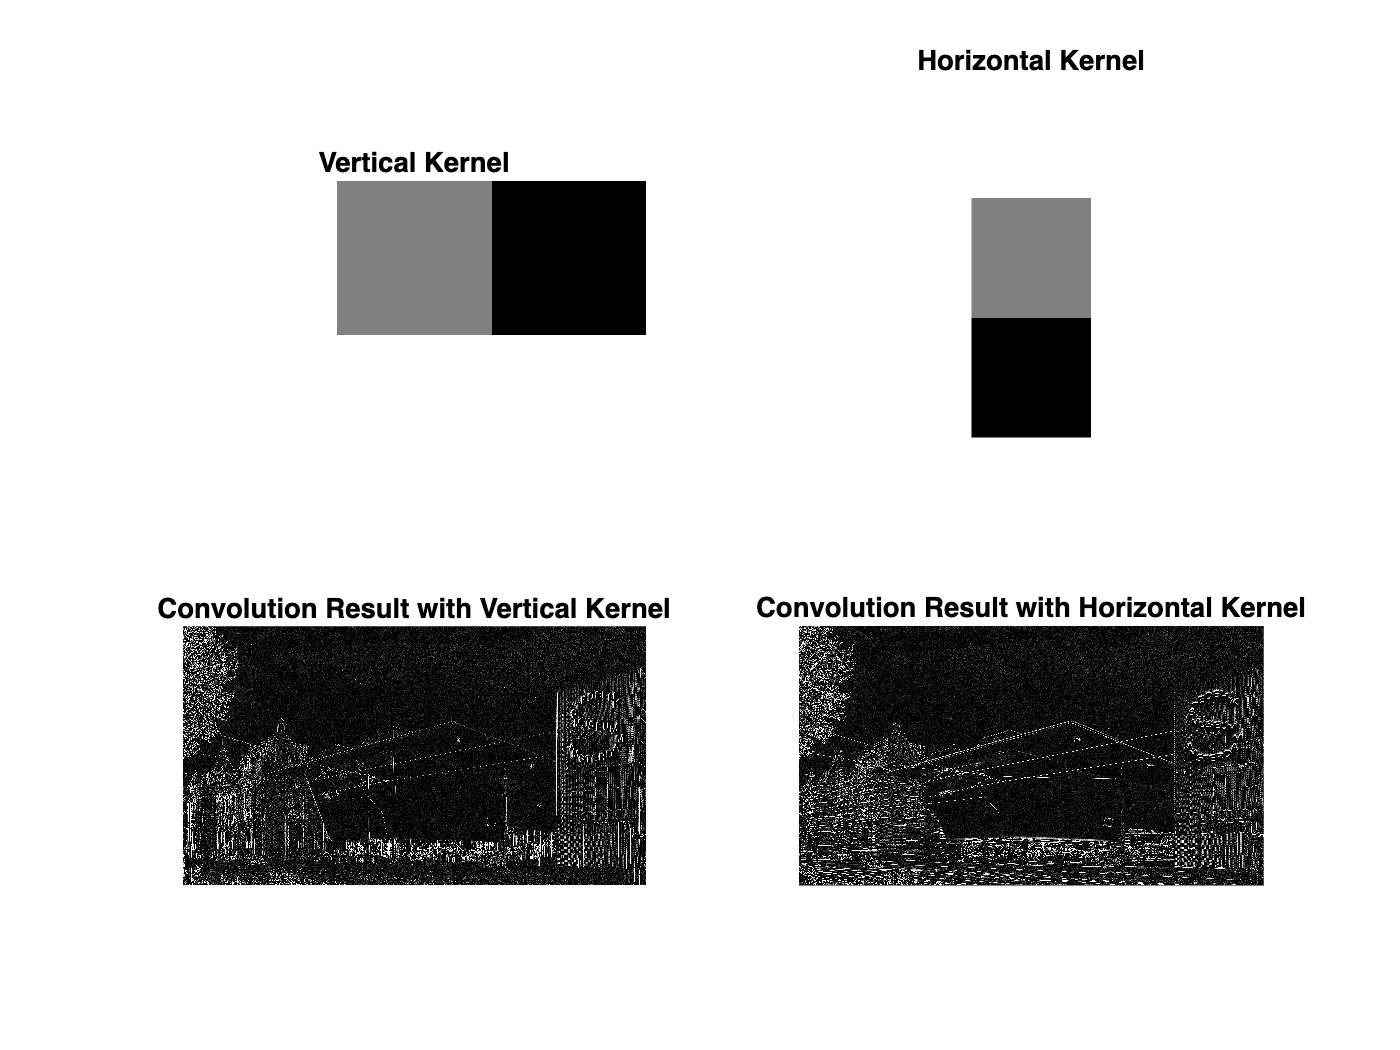


% Convert the image to 2D for convenience (grayscale)
bathtub2d = rgb2gray(bathtub);
bathtub2d = double(bathtub2d);
bathtub2d = (bathtub2d - min(bathtub2d(:))) / (max(bathtub2d(:)) - min(bathtub2d(:)));

% Write here (start)
% Create two feature-detection kernels
VK = [1 0 -1]; % Vertical kernel
HK = [1; 0; -1]; % Horizontal kernel

% Run convolution with the Vertical Kernel
convresVK = conv2(bathtub2d, VK);
% Run convolution with the Horizontal Kernel
convresHK = conv2(bathtub2d, HK);

% Write here (end)

% Display kernels and convolution results
figure;
subplot(2,2,1);
imshow(VK, []);
colormap('gray');
title('Vertical Kernel');

subplot(2,2,2);
imshow(HK, []);
colormap('gray');
title('Horizontal Kernel');

subplot(2,2,3);
imshow(convresVK, [], 'Colormap', gray, 'DisplayRange', [0, max(convresVK(:)) * 0.1]);
axis off;
title('Convolution Result with Vertical Kernel');

subplot(2,2,4);
imshow(convresHK, [], 'Colormap', gray, 'DisplayRange', [0, max(convresHK(:)) * 0.1]);
axis off;
title('Convolution Result with Horizontal Kernel');

### Extra try: Visualization Example

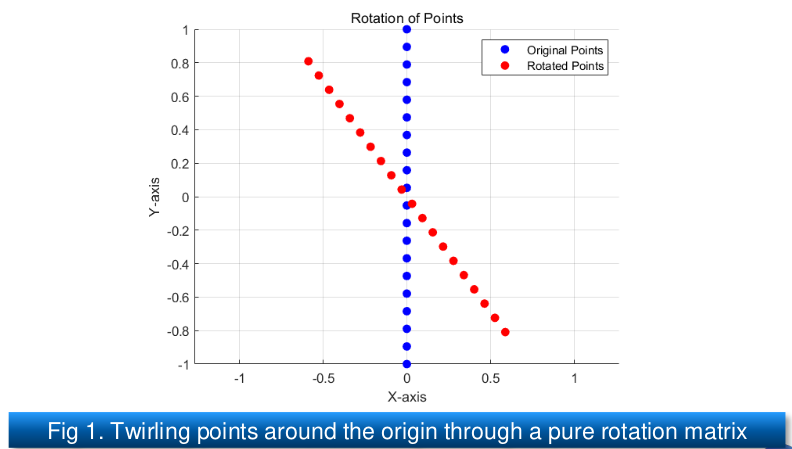

% ■ Consider set of points aligned in a vertical line and effect of multiplying those
%   coordinates by 𝑻.
%      Set 𝜃 = 𝜋/5. How will the results be drawn?
% ■ Before continuing with this section…,
%      Inspect online code that generates this figure.
%      Make sure you understand how Eq 1. is translated into code.
%      Take moment to experiment with different rotation angles.
%      Figure out how to make rotation counterclockwise instead of clockwise as Fig 1..
%         > Answer: Swap minus signs in sine functions

clc; clear; close all;

% y = linspace(-1, 1, 20);
y = -1:0.1:1;
x = zeros(size(y));
plot(x, y, 'b.', MarkerSize=15, DisplayName='Original Points');
hold on;

theta = pi/5

theta = 0.6283

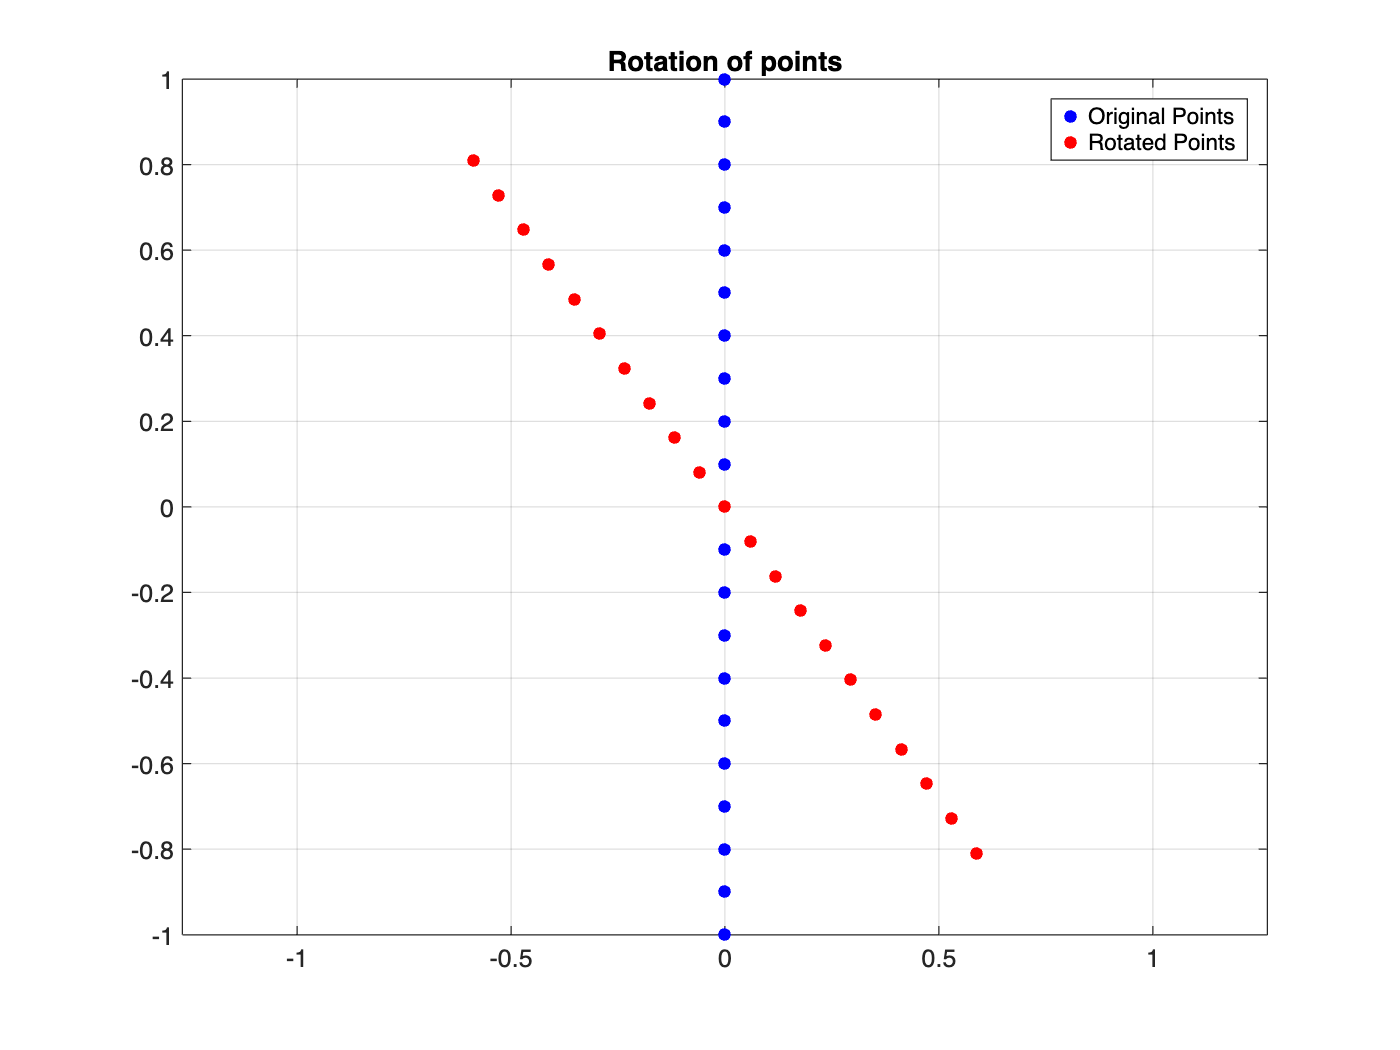

T = [cos(theta) -sin(theta);
    sin(theta), cos(theta)];

points = [x; y];
rotated_points = T * points;

r_x = rotated_points(1, :);  % First row contains x-coordinates
r_y = rotated_points(2, :);  % Second row contains y-coordinates

plot(r_x, r_y, 'r.', 'MarkerSize', 15, DisplayName='Rotated Points');
xlim([-1, 1]);
ylim([-1, 1]);

xlabel = ('X-axis');
ylabel = ('Y-axis');
grid on;
axis equal;

title('Rotation of points');

legend("show");